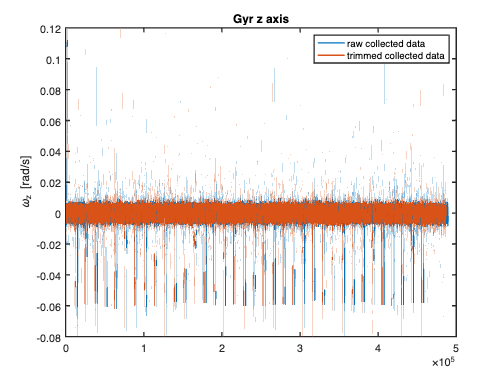

clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

global rowsnotNeeded gyroscale      % puts these values as global parameters to be used in functions

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [15, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Acc_X", "Acc_Y", "Acc_Z", "Gyr_X", "Gyr_Y", "Gyr_Z"];
opts.SelectedVariableNames = ["Acc_X", "Acc_Y", "Acc_Z", "Gyr_X", "Gyr_Y", "Gyr_Z"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9"], "EmptyFieldRule", "auto");

% Import the data
XsensMTiG710 = readtable("XsensMTiG710.txt", opts);
%% Clear temporary variables
clear opts
data1 = table2array(XsensMTiG710);
data2 = data1(:,6); % noisy omega z   
data2(1:2570)=[]; %Trimmed start of data (to remove the movement of turntable from old position to zero)

wz_noisy    = data2;   %% noisy omega z [rad/s] + compensated bias

gyroscale = std(wz_noisy);      % help in normalization

figure
plot(data1(:,6))
hold on
plot(wz_noisy)
legend('raw collected data','trimmed collected data')
title('Gyr z axis')
ylabel('\omega_z [rad/s]')
hold off

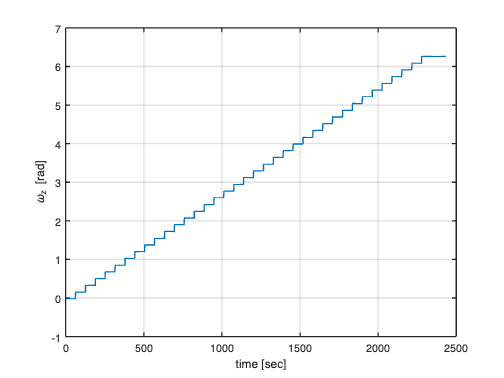

%  psi0=88.7513  --> orentation zero encoder from turntable when statring from 0,0,0; --> the xsens was showing almost to north direction with it x-axis  
psi=[];
psi(1:12640,1) = 0;
psi(12641:25302,1) = 10;
psi(25303:37966,1) = 20;
psi(37967:50631,1) = 30;
psi(50632:63285,1) = 40;
psi(63286:75936,1) = 50;
psi(75937:88607,1) = 60;
psi(88608:101266,1) = 70;
psi(101267:113936,1) = 80;
psi(113937:126605,1) = 90;
psi(126606:139240,1) = 100;
psi(139241:151911,1) = 110;
psi(151912:164561,1) = 120;
psi(164562:177231,1) = 130;
psi(177232:189902,1) = 140;
psi(189903:202561,1) = 150;
psi(202562:215225,1) = 160;
psi(215226:227891,1) = 170;
psi(227892:240540,1) = 180;
psi(240541:253192,1) = 190;
psi(253193:265851,1) = 200;
psi(265852:278503,1) = 210;
psi(278504:291175,1) = 220;
psi(291176:303819,1) = 230;
psi(303820:316491,1) = 240;
psi(316492:329143,1) = 250;
psi(329144:341804,1) = 260;
psi(341805:354460,1) = 270;
psi(354461:367121,1) = 280;
psi(367122:379775,1) = 290;
psi(379776:392432,1) = 300;
psi(392433:405091,1) = 310;
psi(405092:417770,1) = 320;
psi(417771:430411,1) = 330;
psi(430412:443074,1) = 340;
psi(443074:455742,1) = 350;
psi(455743:486956,1) = 360;

psi             = psi-1.2487;      % deg  + azimuth addition though irrelevant

rateSteps       =   linspace(psi(1,1),psi(end,1),37); % 37 is the number of horizontal steps from 0-10 upto 350-360
f_imu           =   200;                              % IMU sample rate in [Hz]
stopDuration    =   length(wz_noisy)/f_imu/37;
t               =   (1/f_imu:1/f_imu:length(rateSteps)* stopDuration)' ; % considered time span for training data; 

% convert signal from deg to rad                      
psi             =   psi*pi/180;                             %  [rad] (error free heading z)

% plot error-free reference signal

figure
plot(t,psi)
xlabel('time [sec]')
ylabel('\omega_z [rad]')
grid on

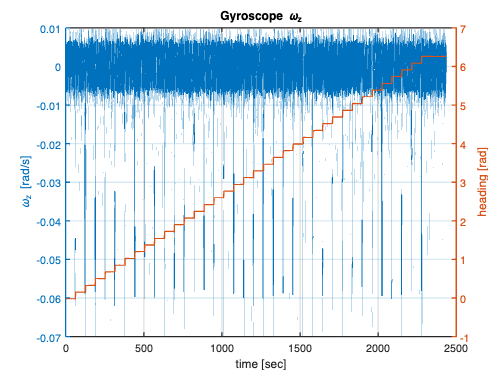

figure
yyaxis left
plot(t,wz_noisy)
ylabel('\omega_z [rad/s]')
hold on
grid on
yyaxis right
plot(t,psi)
hold off
xlabel('time [sec]')
ylabel('heading [rad]')
title('Gyroscope \omega_z')

% % Split the data into training and testing sets
split_ratio             = 0.8; % 80% training, 20% testing
num_samples             = size(wz_noisy, 1);
split_idx_train         = round(split_ratio * num_samples);
split_idx_val           = round(0.8 * num_samples); 


%% split the data to training, validation and testing, including the reference data
%% Training sets
train_data          = wz_noisy(1:split_idx_val, :);
rowsnotNeeded       = find( train_data > 0.01 | train_data < -0.01 ); % get the index of values that satisfy the condition shown

train_data          = num2cell(train_data/gyroscale,1);
train_labels        = num2cell(psi(1:split_idx_val, :),1);

% % Validation sets
% val_data            = num2cell(wz_noisy(split_idx_train+1:split_idx_val, :),1);
% val_labels          = num2cell(psi(split_idx_train+1:split_idx_val, :),1);

%% Testing sets
test_data           = (wz_noisy(split_idx_val+1:end, :))';
test_labels         = (psi(split_idx_val+1:end, :))';

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

train_data{:}       = train_data{:}';
train_labels{:}     = train_labels{:}';

% val_data{:}         = val_data{:}';
% val_labels{:}       = val_labels{:}';

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         3.34 |      2.1e+06 |          0.0003 |
|      50 |          50 |       00:00:11 |         3.32 |      2.0e+06 |          0.0003 |
|     100 |         100 |       00:00:14 |         3.30 |      1.9e+06 |          0.0003 |
|     150 |         150 |       00:00:17 |         3.28 |      1.8e+06 |          0.0003 |
|     200 |         200 |       00:00:20 |         3.26 |      1.7e+06 |          0.0003 |
|     250 |         250 |       00:00:23 |         3.25 |      1.6e+06 |          0.0003 |
|     300 |         300 |       00:00:26 |         3.23 |      1.5

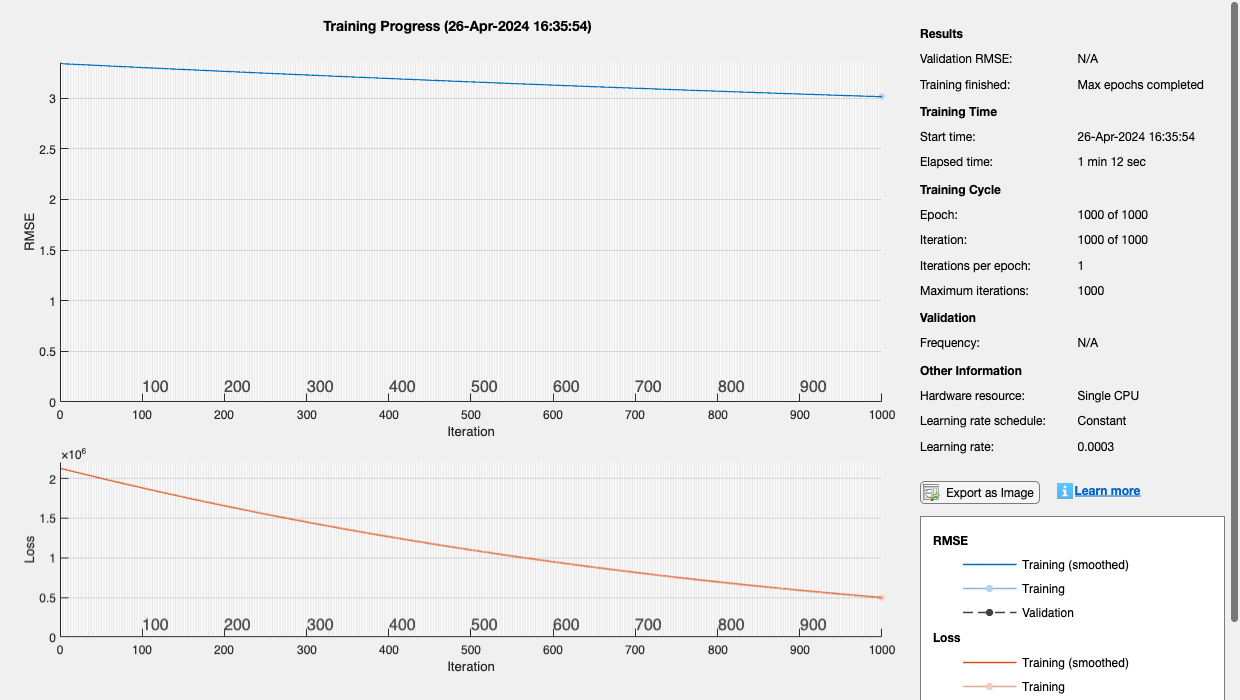

% configure neural network (NN)
numFeatures     = size(train_data, 1); % Number of features in your data
numResponses    = 1;

layers = [
    sequenceInputLayer(numFeatures) 
    fullyConnectedLayer(numResponses, 'Name','output','BiasInitializer','zeros','WeightsInitializer','ones')
    StrapdownRegressionLayer_modified('1D-StrapdownRegression')
];


% Set training options with the Adam optimizer
options = trainingOptions('adam', ...
    'MaxEpochs', 1000, ...
    'MiniBatchSize',4000,...
    'InitialLearnRate', 0.0003, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots','training-progress',...
    'Verbose',1);

% Train the network
net = trainNetwork(train_data, train_labels, layers, options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |         3.01 |     497276.1 |          0.0650 |
|      50 |          50 |       00:00:10 |         2.73 |       8178.7 |          0.0650 |
|     100 |         100 |       00:00:15 |         2.73 |       3382.0 |          0.0650 |
|     150 |         150 |       00:00:18 |         2.73 |       3217.1 |          0.0650 |
|     200 |         200 |       00:00:21 |         2.72 |       3102.9 |          0.0650 |
|     250 |         250 |       00:00:24 |         2.71 |       2967.8 |          0.0650 |
|     300 |         300 |       00:00:27 |         2.71 |       28

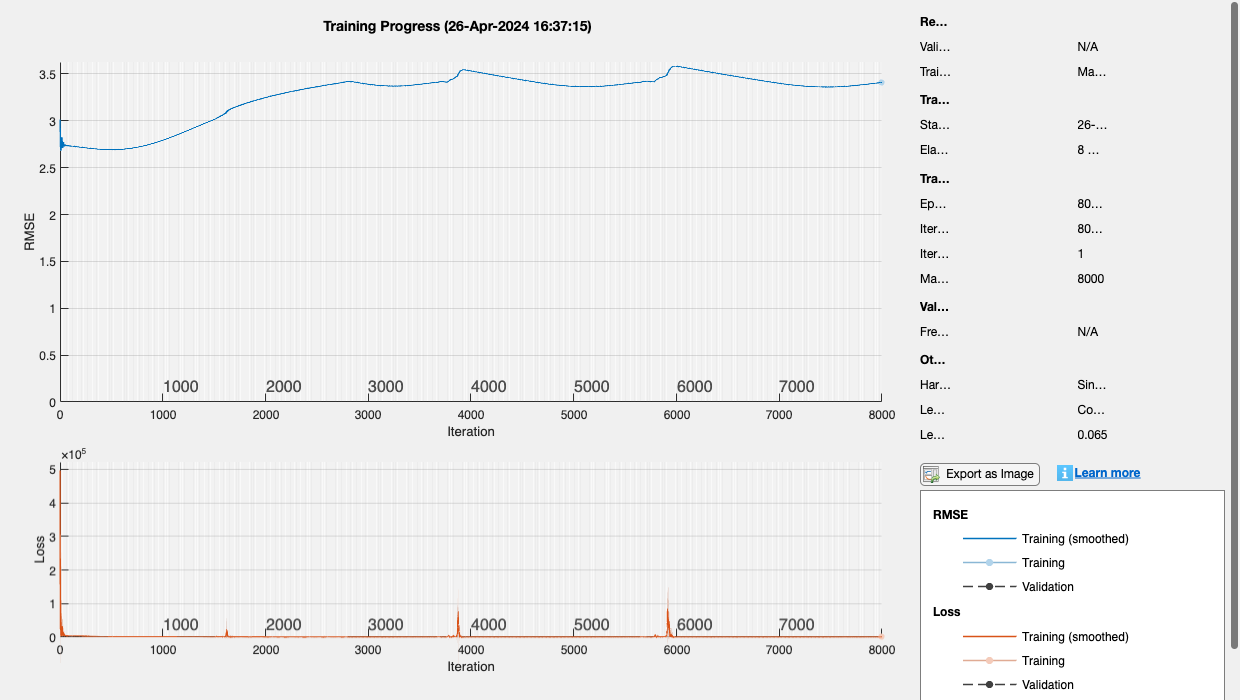

% Re-train the network again
% Set training options with the Adam optimizer
options2 = trainingOptions('adam', ...
    'MaxEpochs', 8000, ...
    'MiniBatchSize',100000,...
    'InitialLearnRate', 0.065, ...
    "Shuffle","never",...
    'ExecutionEnvironment', 'auto', ...
    'Plots','training-progress',...
    'Verbose',1);
net = trainNetwork(train_data, train_labels, net.Layers, options2);

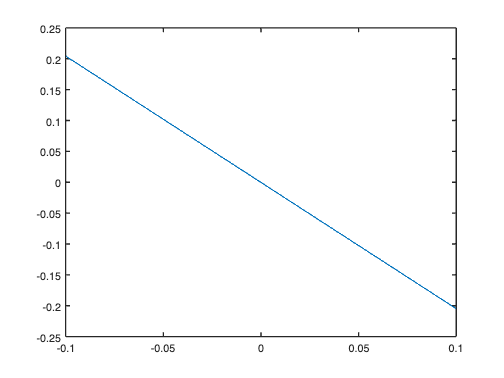

% Plot transfer function of NN
% Expect a 1-1 plot where the raw data and predicted should have a positive
% correlation
input_rate = -0.1:0.0001:0.1;
output_rate = predict(net, input_rate/gyroscale)*gyroscale;
figure;
plot(input_rate,output_rate);


%% Test the trained network
predicted_labels = predict(net, test_data/gyroscale)*gyroscale;
predicted_labels = cumsum(predicted_labels)/f_imu;

%% Course alignement and Plots

predicted_psi0  = predicted_labels + (test_labels(1,1)-predicted_labels(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and
% course alignment done
uncalibrated_data = cumsum(-test_data)/f_imu;
uncalibrated_data = uncalibrated_data + (test_labels(1,1)-uncalibrated_data(1,1)); % course alignment

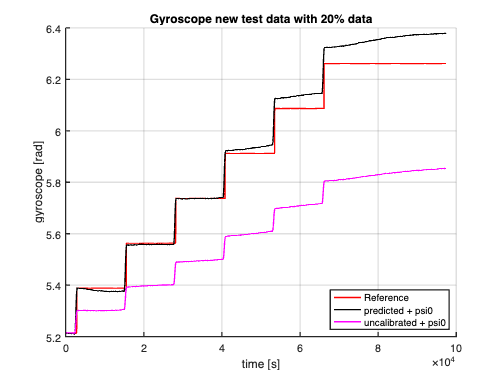

%% Plots
fig1=figure;
% plot(predicted_labels,'b');
hold on;
plot(test_labels, 'r');
plot(predicted_psi0,'k')
plot(uncalibrated_data,'m')
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Reference','predicted + psi0','uncalibrated + psi0','Location','southeast');
title('Gyroscope new test data with 20% data');
exportgraphics(fig1,'Gyroscope new test data with 20% data.png','Resolution',300);

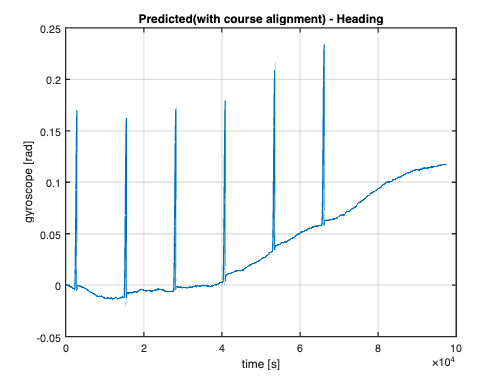

fig2=figure;
plot(predicted_psi0 - test_labels)
xlabel('time [s]');
ylabel('gyroscope [rad]');
grid on
title('Predicted(with course alignment) - Heading');
exportgraphics(fig2,'Difference between Predicted(with course alignment) and Heading.png','Resolution',300);